### `Performing Exploratory Data Analysis (EDA)`

`1. Load the cleaned dataset`

% Load the cleaned dataset
data = readtable('cleaned_bangalore_zomato_data.csv');

`2. Univarate Analysis`

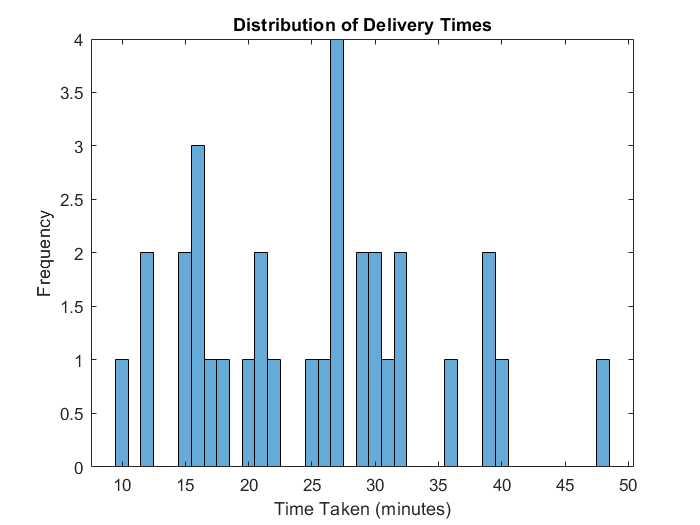

% Univariate Analysis
figure
histogram(data.Time_taken_min);
title('Distribution of Delivery Times');
xlabel('Time Taken (minutes)');
ylabel('Frequency');

drawnow;

`3. Bivariate Analysis`

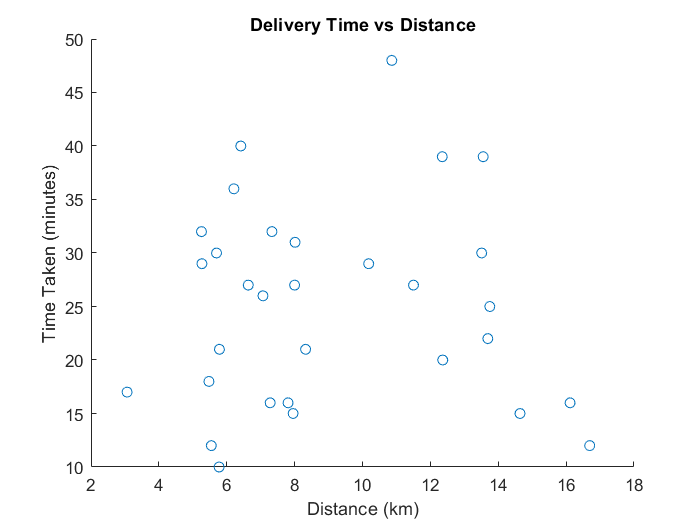

% Bivariate Analysis
figure
scatter(data.Distance, data.Time_taken_min);
title('Delivery Time vs Distance');
xlabel('Distance (km)');
ylabel('Time Taken (minutes)');

drawnow;

`4. Multivariate Analysis`

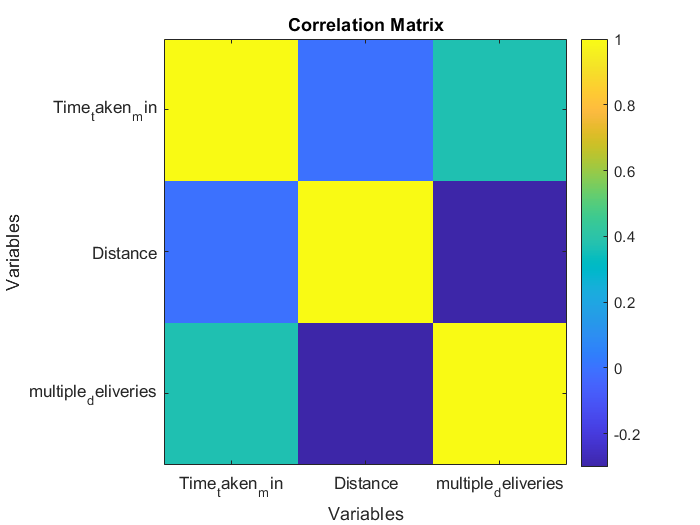

% Multivariate Analysis
% Correlation Matrix
numericalVars = table2array(data(:, {'Time_taken_min', 'Distance', ...
    'multiple_deliveries'}));
corrMatrix = corr(numericalVars, 'Type', 'Pearson');

figure;
imagesc(corrMatrix);
colorbar;
title('Correlation Matrix');
xlabel('Variables');
ylabel('Variables');
set(gca, 'XTick', 1:length(data.Properties.VariableNames), 'XTickLabel', ...
    {'Time_taken_min', 'Distance', 'multiple_deliveries'});
set(gca, 'YTick', 1:length(data.Properties.VariableNames), 'YTickLabel', ...
    {'Time_taken_min', 'Distance', 'multiple_deliveries'});

drawnow;

`5. Categorical Data Analysis (Two examples are used)`

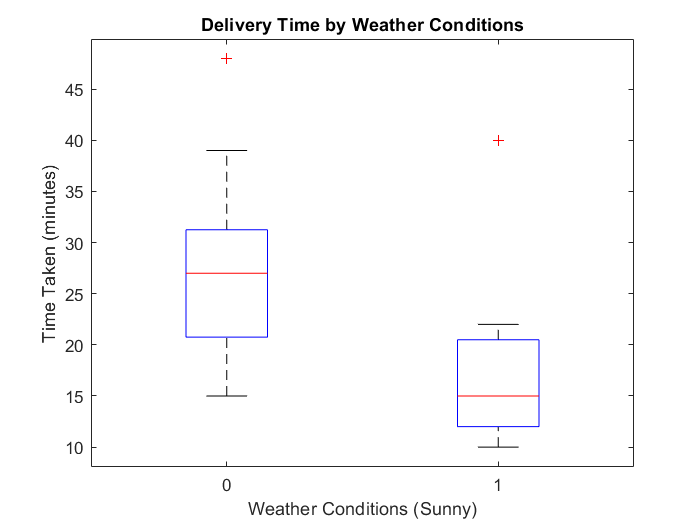

% Categorical Data Analysis
figure;
boxplot(data.Time_taken_min, data.Weather_conditions_Sunny); 
title('Delivery Time by Weather Conditions');
xlabel('Weather Conditions (Sunny)');
ylabel('Time Taken (minutes)');

drawnow;

`6. Box Plot of Delivery Times by Traffic Density`

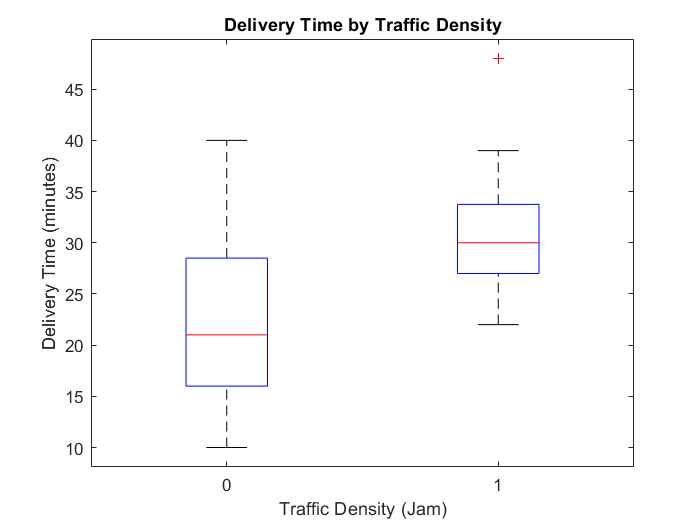

% Box Plot of Delivery Times by Traffic Density
figure;
boxplot(data.Time_taken_min, data.Road_traffic_density_Jam); 
title('Delivery Time by Traffic Density');
xlabel('Traffic Density (Jam)');
ylabel('Delivery Time (minutes)');

drawnow;

`7. Descriptive Statistics`

% Descriptive Statistics
meanTime = mean(data.Time_taken_min);
medianTime = median(data.Time_taken_min);
stdTime = std(data.Time_taken_min);
minTime = min(data.Time_taken_min);
maxTime = max(data.Time_taken_min);

disp(['Mean Delivery Time: ', num2str(meanTime), ' minutes']);

Mean Delivery Time: 25.1562 minutes


disp(['Median Delivery Time: ', num2str(medianTime), ' minutes']);

Median Delivery Time: 26.5 minutes


disp(['Standard Deviation of Delivery Time: ', num2str(stdTime), ' minutes']);

Standard Deviation of Delivery Time: 9.3053 minutes


disp(['Minimum Delivery Time: ', num2str(minTime), ' minutes']);

Minimum Delivery Time: 10 minutes


disp(['Maximum Delivery Time: ', num2str(maxTime), ' minutes']);

Maximum Delivery Time: 48 minutes


`8. Linear Regression Analysis`

% Linear Regression Analysis
mdl = fitlm(data.Distance, data.Time_taken_min);
disp('Linear Regression Model:');

Linear Regression Model:


disp(mdl);

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)      25.287     4.4864      5.6364    3.8667e-06
    x1             -0.01451    0.46136    -0.03145       0.97512


Number of observations: 32, Error degrees of freedom: 30
Root Mean Squared Error: 9.46
R-squared: 3.3e-05,  Adjusted R-Squared: -0.0333
F-statistic vs. constant model: 0.000989, p-value = 0.975
